global N J tmax Nt NA NV phi delta loop method;

N=400;          %粒子链总长度
J=100;          %相互作用强度
tmax=3;       %模拟时间
Nt=1000;         %时间采样数
NA=100;         %波包初态中心位置
NV=200;         %散射粒子位置
phi=pi/2;
delta=30;      %波包半宽
loop=true;
method='ode';          
V=1*J;

psi0 = GaussianState(N,NA,phi,delta);
H = Hamilton(N,J,loop);
for ii = (N-50):N
    H(ii,ii) = -1*(abs(ii-N+50))*1i;
end
for ii = 1:50
    H(ii,ii) = -1*(abs(ii-50))*1i;
end

H(NV,NV) = V;
[VEC,D] = eig(H);
tic
[t,psi] = psicalc(H,psi0,tmax,method);
toc

历时 3.076153 秒。


Vs = (0:0.2:5)*J;
for ii=1:length(Vs)
    
end

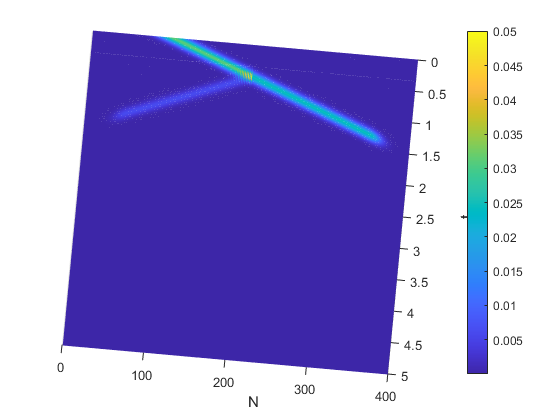

%ode方法数据太多，画图容易卡，抽样一部分用来画图即可
if strcmp(method,'ode')
    dt=floor( length(t) / Nt );
    tplot=t(1:dt:end);
    psiplot=psi(1:dt:end,:);
else
    tplot=t;
    psiplot=psi;
end

plotpsi(psiplot,tplot,N)

function [t,psi] = psicalc(H,psi0,tmax,method)
global VEC D Nt;
    if strcmp(method,'ode')
        [t,psi] = psicalc_ode(H,psi0,tmax);
    elseif strcmp(method,'expm')
        [t,psi] = psicalc_expm(H,psi0,tmax,Nt);
    elseif strcmp(method,'eig')
        [t,psi] = psicalc_eig(VEC,D,psi0,tmax,Nt);
    end
end



